clc; clearvars; close all; 
data= readmatrix("time_pure_purenBD_purenBDRand.txt");

t_vec    = data(:,1);
s0       = data(:,2);
s_0123   = data(:,3);
s_0123_r = data(:,4);
signals  = data(:,2:4);

dt= t_vec(2)-t_vec(1);
fs= 1/dt;
T= t_vec(end);
df= 1/T;
N= length(t_vec);

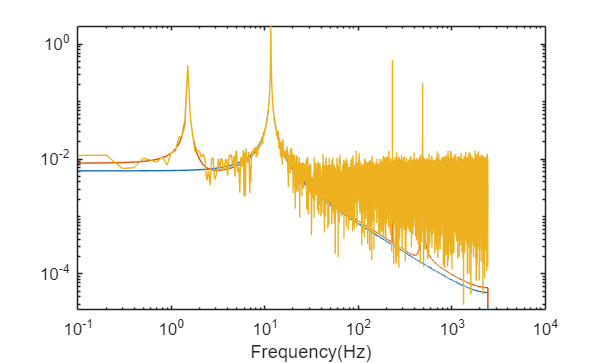

f_vec_1_side = (0:N/2)*df;
y= fft(signals);
p2= abs(y/N);
p1= p2(1:floor(N/2)+1,:);
p1(2:end-1,:)= 2*p1(2:end-1,:);
loglog(f_vec_1_side,p1)
xlabel('Frequency(Hz)')

low_butter_n=4; low_butter_fc=20;
[b_low_butter, a_low_butter]= butter(low_butter_n,low_butter_fc*2*pi,"low","s");
lpf_butter= tf(b_low_butter, a_low_butter);

high_butter_n=4; high_butter_fc=6;
[b_high_butter, a_high_butter]= butter(high_butter_n,high_butter_fc*2*pi,"high","s");
hpf_butter= tf(b_high_butter, a_high_butter);

bpf_butter= hpf_butter* lpf_butter;

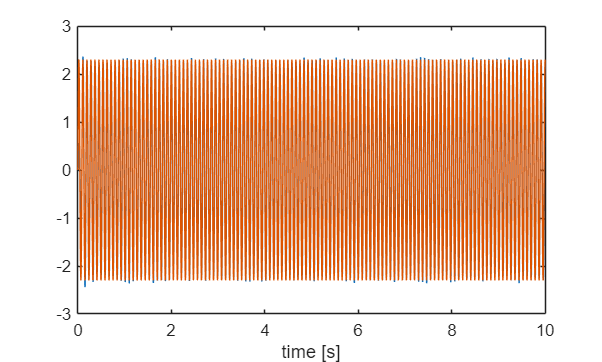

s_filter_butter= lsim(bpf_butter,s_0123_r,t_vec);

plot(t_vec,[s_filter_butter s0])
xlabel('time [s]')

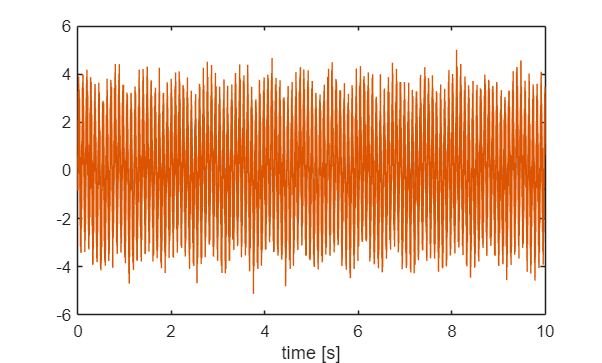


plot(t_vec,[s_filter_butter s_0123_r])
xlabel('time [s]')

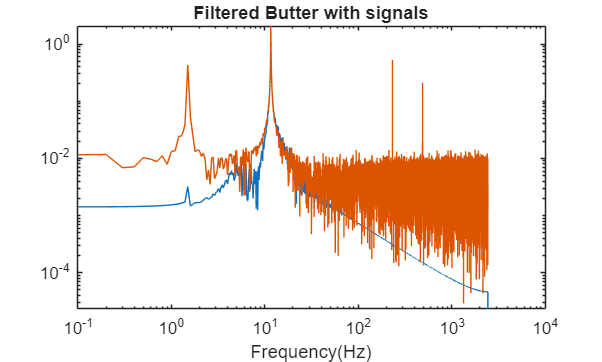

yf_butter= fft(s_filter_butter);
p2f_butter=abs(yf_butter/N);
p1f_butter= p2f_butter(1:floor(N/2)+1,:);
p1f_butter(2:end-1,:)=2*p1f_butter(2:end-1,:);

loglog(f_vec_1_side,[p1f_butter p1(:,end)])
xlabel('Frequency(Hz)')
title('Filtered Butter with signals')

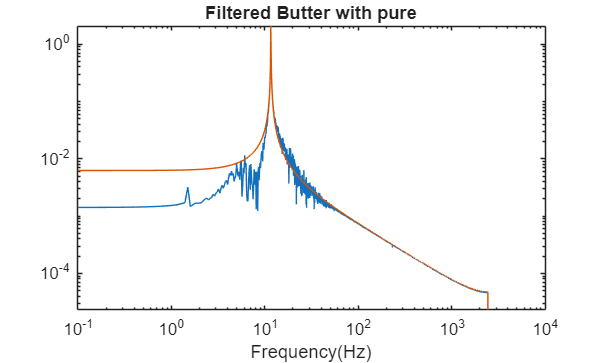


loglog(f_vec_1_side,[p1f_butter p1(:,1)])
xlabel('Frequency(Hz)')
title('Filtered Butter with pure')

low_elliptic_n=3; low_elliptic_fc=20; Rp=0.1; Rs=60;
[b_low_elliptic, a_low_elliptic]= ellip(low_elliptic_n,Rp,Rs,low_elliptic_fc*2*pi,"low","s")

b_low_elliptic = 1.0e+06 *

         0    0.0000   -0.0000    3.2727


a_low_elliptic = 1.0e+06 *

    0.0000    0.0002    0.0414    3.2727


lpf_elliptic= tf(b_low_elliptic, a_low_elliptic);

high_elliptic_n=3; high_elliptic_fc=6; Rp2=0.1; Rs2=30;
[b_high_elliptic, a_high_elliptic]= ellip(high_elliptic_n,Rp2,Rs2,high_elliptic_fc*2*pi,"high","s")

b_high_elliptic =     1.0000    0.0000  180.8018   -0.0000


a_high_elliptic = 1.0e+04 *

    0.0001    0.0055    0.1539    3.0593


hpf_elliptic= tf(b_high_elliptic, a_high_elliptic);

bpf_elliptic= hpf_elliptic*lpf_elliptic;

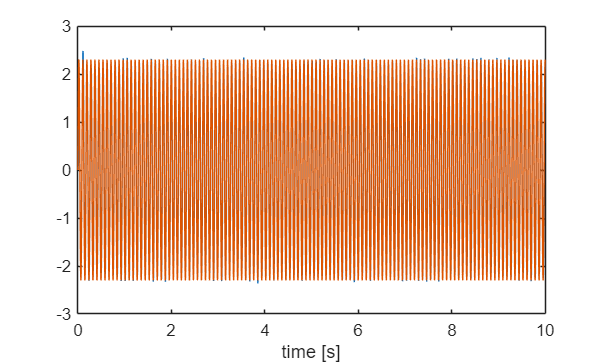

s_filter_elliptic= lsim(bpf_elliptic,s_0123_r,t_vec);

plot(t_vec,[s_filter_elliptic s0])
xlabel('time [s]')

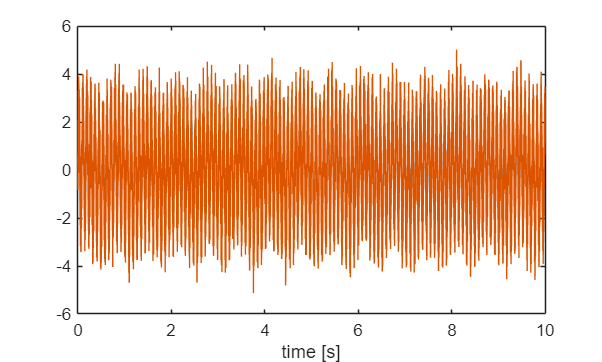


plot(t_vec,[s_filter_elliptic s_0123_r])
xlabel('time [s]')

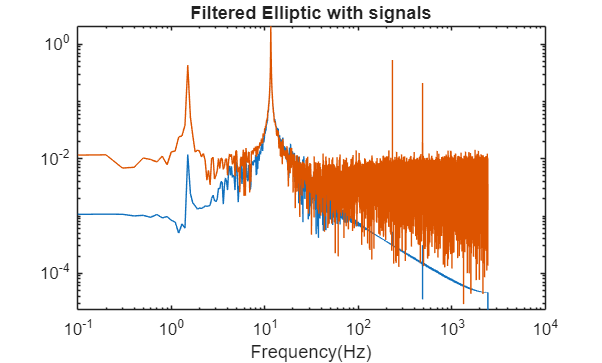

yf_elliptic= fft(s_filter_elliptic);
p2f_elliptic=abs(yf_elliptic/N);
p1f_elliptic= p2f_elliptic(1:floor(N/2)+1,:);
p1f_elliptic(2:end-1,:)=2*p1f_elliptic(2:end-1,:);

loglog(f_vec_1_side,[p1f_elliptic p1(:,end)])
xlabel('Frequency(Hz)')
title('Filtered Elliptic with signals')

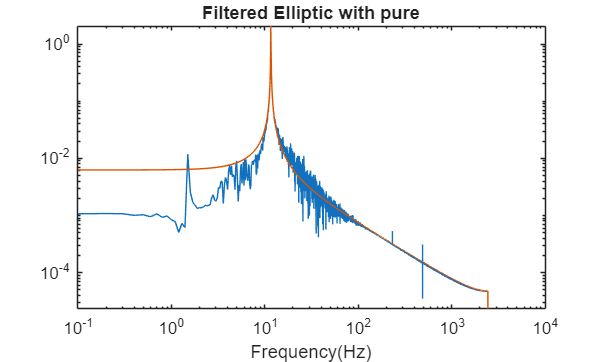


loglog(f_vec_1_side,[p1f_elliptic p1(:,1)])
xlabel('Frequency(Hz)')
title('Filtered Elliptic with pure')

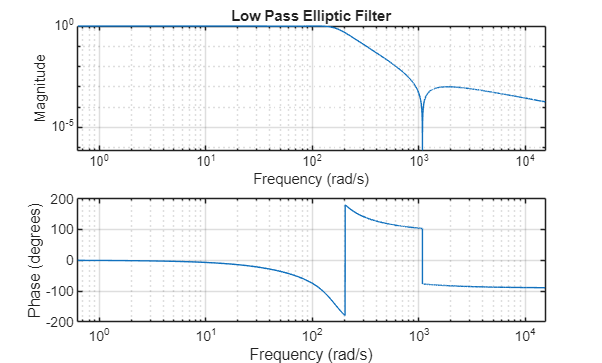

figure()
freqs(b_low_elliptic,a_low_elliptic,f_vec_1_side*2*pi)
title('Low Pass Elliptic Filter')

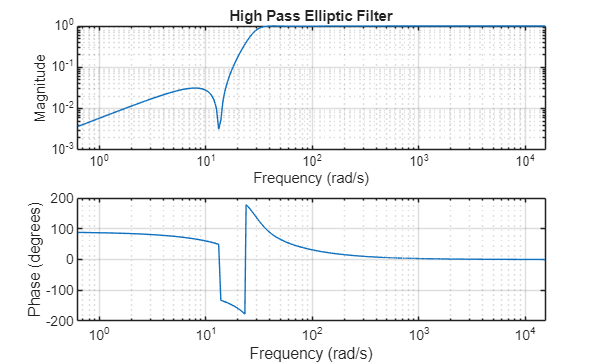


figure()
freqs(b_high_elliptic,a_high_elliptic,f_vec_1_side*2*pi)
title('High Pass Elliptic Filter')

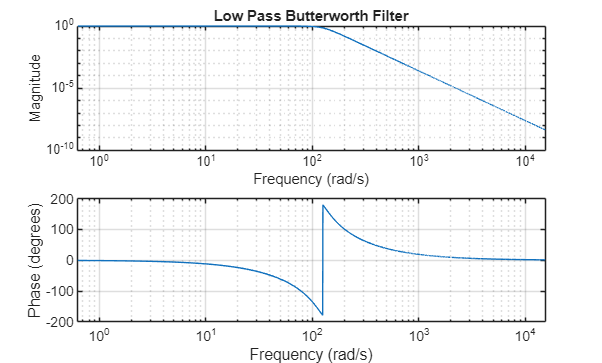


figure()
freqs(b_low_butter,a_low_butter,f_vec_1_side*2*pi)
title('Low Pass Butterworth Filter')

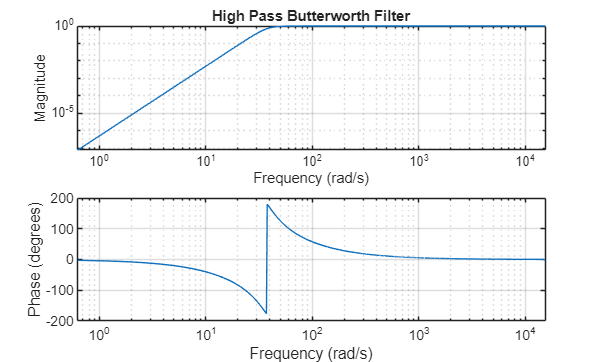


figure()
freqs(b_high_butter,a_high_butter,f_vec_1_side*2*pi)
title('High Pass Butterworth Filter')